# **Segmentació (binaritzat)**

## **Binarització Global**

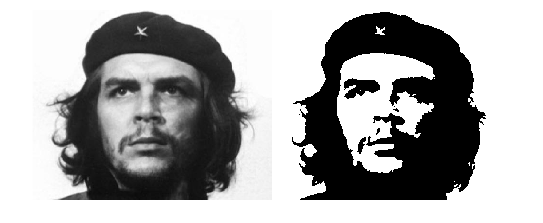

I = rgb2gray(imread('Che.jpg'));
llindar = 115;
BW = I > llindar;
montage({I, BW});

## Binarització amb 2 llindars

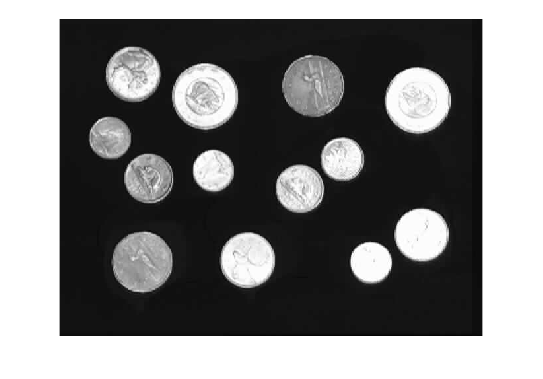

I = imread('money.tif');
imshow(I);

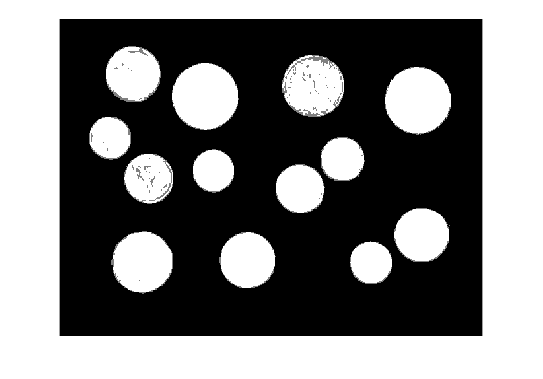

H = I > 128;
L = I < 50;
M = H == L;
R = H*2 + M;
imshow(R, []);

## Binarització per àrea

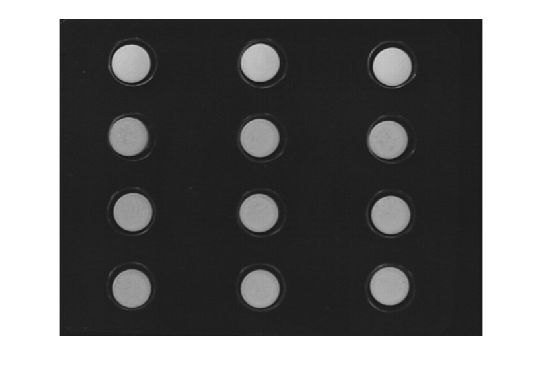

I = rgb2gray(imread('Blispac2.tif'));
imshow(I);

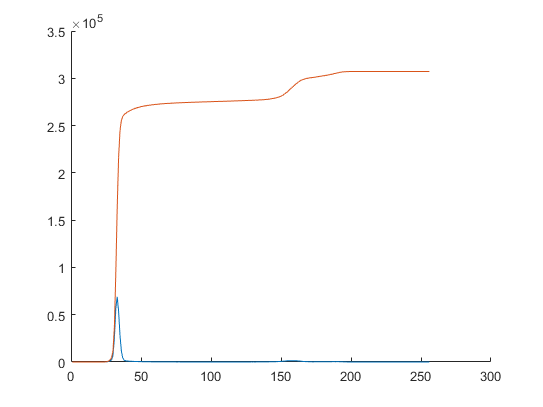

h = imhist(I);
hacum = cumsum(h);
figure
hold on
plot(h);
plot(hacum);
hold off

[f, c] = size(I); 
area = 12*(28.5^2*pi);
valor = f*c - area;
bhacum = hacum > valor;
llindar = find(bhacum, 1);
BW = I > llindar;
n_pixels = sum(BW, 'all')

n_pixels = 30500

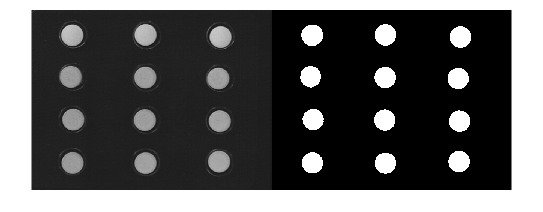

montage({I, BW});

## Binarització per Selecció de Llindar (Otsu)

I = rgb2gray(imread('Blispac2.tif'));
imshow(I);

h = imhist(I);
n_pixels = size(I, 1)*size(I, 2);
hprob = h/n_pixels;
o2b = zeros(256,1);
for i=1:255
    w1 = sum(hprob(1:i));
    w2 = 1 - w1;
    mean1 = sum(h(1:i).*hprob(1:i))/w1;
    mean2 = sum(h(i:255).*hprob(i:255))/w2;
    o2b = w1*w2*(mean1-mean2)^2;
end
max_o2b = max(o2b);
llindar = find(o2b, 1);
BW = I > llindar;
C = bwconncomp(BW);